# TP 2 - Approximation of an EDP

*Aicha Maaoui*

clear all
close all
clc

**Time discretisation**

T = 1; % Time
nt = 100; % Number of points according to t
delta_t = T/(nt-1); % Time step
lt=linspace(0,T,nt); % Time axis

**Space discretisation**

L = 10; % Space 
nx = 1000; % Number of points according to x
delta_x = L/(nx-1); % Space step
lx=linspace(0,L,nx); % Space axis

**Define the symmetric rigidity matrix K**

K = 2 * diag(ones(1,nx)) - diag(ones(1,nx-1),-1) - diag(ones(1,nx-1),1);
K(1,1) = 1; 
K(nx,nx) = 1; 
K = K/delta_x;

**Define the assembly matrix for integration**

% Space integration
Ix = (diag(ones(1,nx-1),-1) + 4*diag(ones(1,nx)) + diag(ones(1,nx-1),1));
Ix(1,1) = 2; 
Ix(nx,nx) = 2;
Ix = Ix * (delta_x/6);

% Time integration
It = (diag(ones(1,nt-1),-1) + 4*diag(ones(1,nt)) + diag(ones(1,nt-1),1));
It(1,1) = 2; 
It(nt,nt) = 2;
It = It * (delta_t/6);

**Compute the force F**

%f = zeros(nx, nt); % force matrix
f = 5 * sin(3 * pi * lx / L)' * sin(2 * pi * lt / T);
%f = 3 * cos(3 * (pi/3) * lx / L)' * cos(2 * (pi/3) * lt / T);
F = Ix * f;

**Calculate the DOF indices**

lddl = 1:nx; % entire indices list
lddld = [1,nx]; % indices of boundary conditions 
lddlu = lddl;
lddlu(lddld) = []; % delete boundary conditions indices

**Define the prescribed displacement**

%Ud_0 = sin(pi*lt/T); 
%Ud_L = sin(2 * pi*lt/T);
Ud_0 = 8*sin(2 * pi*lt/T); % at x =0
Ud_L = -5*sin(4 * pi*lt/T); % at x =L

### **Brute Force algorithm**

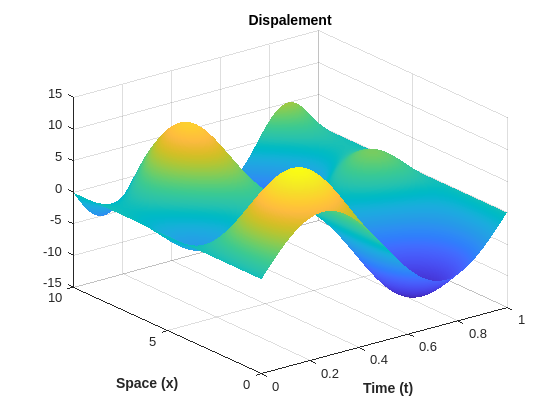

% Initialization
Uref = zeros(nx, nt);
Uk = zeros(nx, 1);

% Compute the K blocs
Kuu = K(lddlu,lddlu);
Kud = K(lddlu,lddld);

for k = 1:nt
    % Solve the displacement
    Fk = F(:,k);
    Fu = Fk(lddlu,1);
    Ud = [Ud_0(k); Ud_L(k)];    
    Uk(lddlu) = Kuu\(Fu - Kud * Ud);
    Uk(lddld) = Ud;
    Uref(:, k) = Uk;
end

% Uref Suface plotting
figure()
surf(lt,lx,Uref);
xlabel('Time (t)', 'FontWeight','bold')
ylabel('Space (x)', 'FontWeight','bold')
title('Dispalement', 'FontWeight','bold')
shading interp;

### **PGD algorithm (without orthogonalization)**

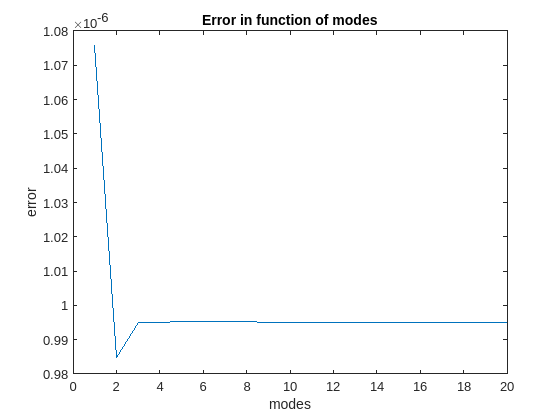

% Calculate prescribed U (boundary condition)
Ucl = (1-(lx/L))' * Ud_0 + (lx/L)' * Ud_L;

% Calculate G
G = F - K * Ucl;

% Define the number of modes (for data compression)
n_modes = 20;

%% Greedy algorithm + fixed point

% Initialization
Gamma = zeros(nt, n_modes);  % Time dependent
Lambda = zeros(nx, n_modes);   % Space dependent 
Lambda_new = zeros(nx,1);
U_PGD = Ucl;  % Field to approximate (initialized to boundary condition)
PGD_error = zeros(n_modes,1);

% Define a threshold
Threshold = 1e-3;
% Loop on the number of modes
for mode = 1:n_modes

    % Add new mode 
    U_star = Uref - U_PGD; % Field to approximate

    gamma_new = lt'; % initialization of gamma_new
    
    s=0.5;
    % Fixed point algorithm
    while (s> Threshold)
    
        % Save old function Gamma
        gamma_old = gamma_new;
                
        % Compute new time function
        H = gamma_new' * It * gamma_new * K;
        J = (gamma_new' * It * G')';
        Ju = J(lddlu);
        Lambda_new(lddlu) = H(lddlu,lddlu) \ Ju;
        %Lambda_new(lddld) = 0;
                
        % Normalisation
        Lambda_new = Lambda_new / sqrt(Lambda_new' * K * Lambda_new); 

        % Compute new space function
        gamma_new = (Lambda_new' * G)';
                
        % update stagnation criteria
        s = ((gamma_new - gamma_old)' * It * (gamma_new - gamma_old)) / (gamma_old' * It * gamma_old);
            
    end 

%     % Calculate the approximation error
%     err = norm(Uref-U_PGD)/norm(Uref);
%     PGD_error(mode) = sqrt(err);

    % Save the modes
    Lambda(:,mode) = Lambda_new;
    Gamma(:,mode) = gamma_new;

    % Update G
    G = G - K * Lambda_new * gamma_new';

    % Update the field to approximate
    U_PGD = U_PGD + Lambda_new * gamma_new';

    % Update the field to approximate
    U_star = U_star - Lambda_new * gamma_new';

    % Calculate the approximation error
    err = norm(Uref-U_PGD)/norm(Uref);
    PGD_error(mode) = sqrt(err);
   
end

% Plot approximation error
figure()
plot(1:n_modes,PGD_error);
title('Error in function of modes')
xlabel('modes')
ylabel('error')

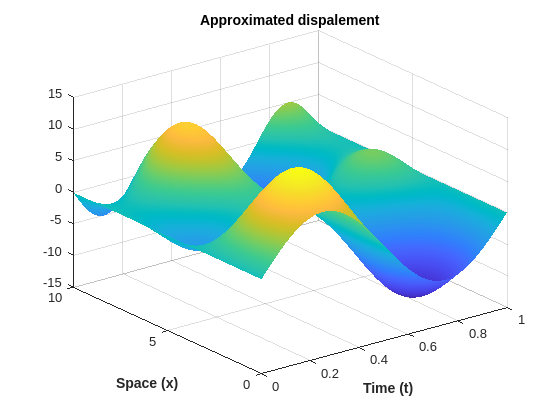

%semilogy(1:n_modes,PGD_error);

% Plot approximated field
figure()
surf(lt,lx,U_PGD);
xlabel('Time (t)', 'FontWeight','bold')
ylabel('Space (x)', 'FontWeight','bold')
title('Approximated dispalement', 'FontWeight','bold')
shading interp;

### **PGD algorithm (with orthogonalization - Gram-Schmidt)**

% Calculate G
G = F - K * Ucl;

% Initialization
Gamma = zeros(nt, n_modes);  % Time dependent
Lambda = zeros(nx, n_modes);   % Space dependent 
Lambda_new = zeros(nx,1);
U_PGD_orth = Ucl;  % Field to approximate (initialized to boundary condition)
PGD_error_orth = zeros(n_modes,1);

integration1_t_orth = zeros(nt,1);
integration2_t_orth = zeros(nt,1);

% Define a threshold
Threshold = 1e-3;
% Loop on the number of modes
for mode = 1:n_modes

    % Add new mode 
    U_star = Uref - U_PGD_orth; % Field to approximate

    gamma_new = lt'; % initialization of gamma_new
    
    s=1;
    % Fixed point algorithm
    while (s> Threshold)
    
        % Save old function Gamma
        gamma_old = gamma_new;
                
        % Compute new time function
        H = gamma_new' * It * gamma_new * K;
        J = (gamma_new' * It * G')';
        Ju = J(lddlu);
        Lambda_new(lddlu) = H(lddlu,lddlu) \ Ju;
                
        % Normalisation
        Lambda_new = Lambda_new / sqrt(Lambda_new' * K * Lambda_new); 

        % Compute new space function
        gamma_new = (Lambda_new' * G)';
                
        % update stagnation criteria
        s = ((gamma_new - gamma_old)' * It * (gamma_new - gamma_old)) / (gamma_old' * It * gamma_old);
            
    end

    % Save the modes
    Lambda(:,mode) = Lambda_new;
    Gamma(:,mode) = gamma_new;


    % Update G
    G = G - K * Lambda_new * gamma_new';

    % Update the field to approximate
    U_PGD_orth = U_PGD_orth + Lambda_new * gamma_new';

    % Update the field to approximate
    U_star = U_star - Lambda_new * gamma_new';

    %% Orthogonalization with Gram-Scmidt
    sum_orth = 0;
    for i = 1:(mode-1)
        sum_orth = sum_orth + (Lambda_new' * Ix * Lambda(:, i)) * Lambda(:, i);
        Gamma(:, i) = Gamma(:, i) + gamma_new * (Lambda_new' * Ix * Lambda(:, i));
    end
    
    Lambda_tmp = Lambda_new - sum_orth; % orthogonalized version of "Lambda_new"
        
    % Normalize the new mode
    Lambda_tmp = Lambda_tmp /sqrt(Lambda_tmp' * Ix * Lambda_tmp);
    gamma_new = gamma_new * sqrt(Lambda_tmp' * Ix * Lambda_tmp);
    
    % Save the normalized mode
    Lambda(:,mode) = Lambda_tmp;
    Gamma(:,mode) = gamma_new;

    % Calculate the approximation error
    err_orth = norm(Uref-U_PGD_orth)/norm(Uref);
    PGD_error_orth(mode) = sqrt(err_orth);

end

% Plot approximation error
figure()
plot(1:n_modes,PGD_error_orth);
title('Error in function of modes')
xlabel('modes')
ylabel('error')

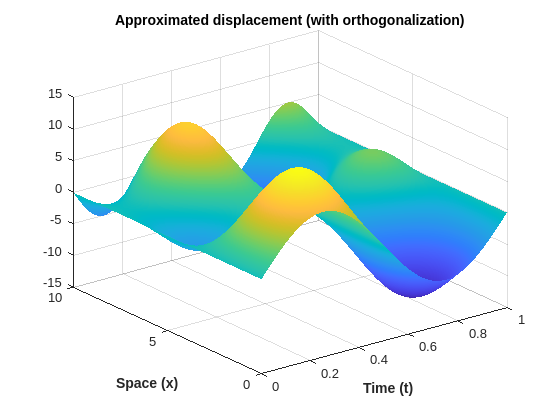


% Plot approximated field
figure()
surf(lt,lx,U_PGD_orth);
xlabel('Time (t)', 'FontWeight','bold')
ylabel('Space (x)', 'FontWeight','bold')
title('Approximated displacement (with orthogonalization)', 'FontWeight','bold')
shading interp;

**Comparison between PGD without and with orthogonalization**

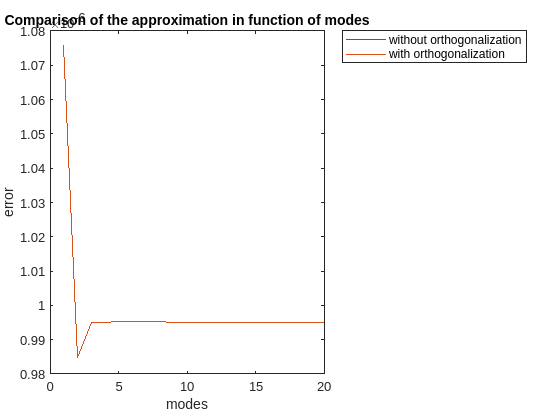

plot(1:n_modes,PGD_error,1:n_modes,PGD_error_orth);
title('Comparison of the approximation in function of modes')
xlabel('modes')
ylabel('error')
legend('without orthogonalization', 'with orthogonalization');

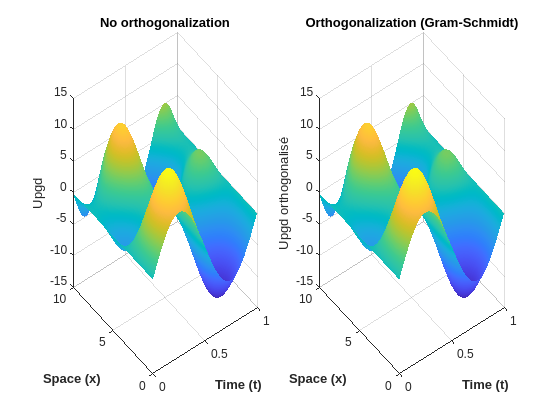

% Display distribution
subplot(1,2,1)
surf(lt,lx,U_PGD)
xlabel('Time (t)', 'FontWeight','bold')
ylabel('Space (x)', 'FontWeight','bold')
zlabel('Upgd')
title('No orthogonalization', 'FontWeight','bold')
shading interp

subplot(1,2,2)
surf(lt,lx,U_PGD_orth)
xlabel('Time (t)', 'FontWeight','bold')
ylabel('Space (x)', 'FontWeight','bold')
zlabel('Upgd orthogonalisé')
title('Orthogonalization (Gram-Schmidt)', 'FontWeight','bold')
shading interp